# Model Overview

This document provides an overview of the various components and subsystems of the Electric VTOL model.

Copyright 2025 The MathWorks, Inc.

To return to the main page within this repository, [click here](matlab:web('EVTOLDesignOverview.html')).

## Model

This model is built upon the "Customize VTOL UAV Configuration" example from MATLAB, which offers detailed guidance on integrating custom control systems and aircraft dynamics into a VTOL UAV template. To access the example, in the MATLAB® Command Window enter this command. 

`openExample(``'uav/CustomizeVTOLConfigurationForYourApplicationExample'``)`

The Electric VTOL model here integrates Simscape™ physical components for the motor, propeller, and battery into the powertrain architecture. Open the `EVTOLTiltrotor` model.

open('EVTOLTiltrotor');

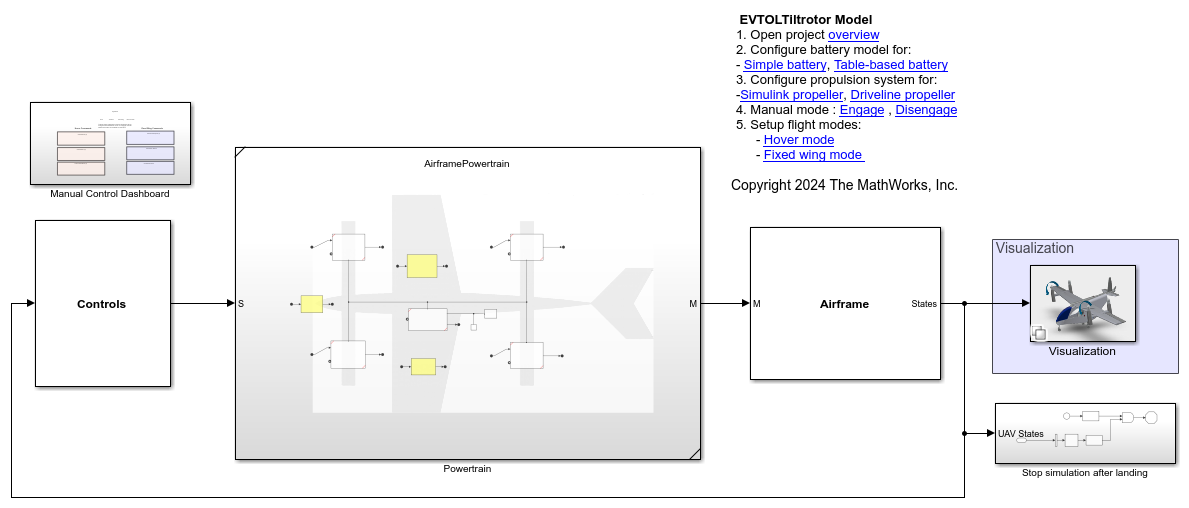

The powertrain includes four motors that drive the four propellers, with two motors positioned in front of the wing and two behind. A Table-Based Battery block powers the motors.

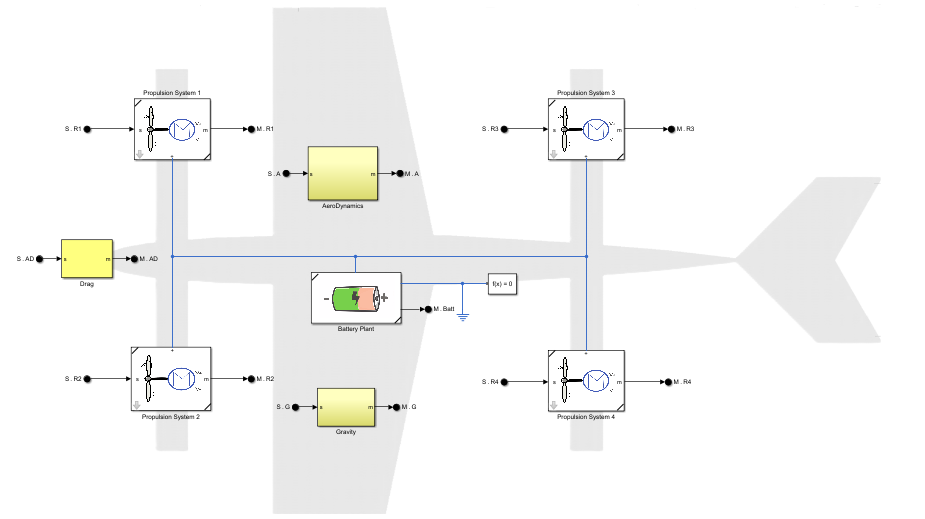

The forces acting on an aircraft include:

- **Thrust generated by the propulsion system —** Acts in the direction of forward motion. In hover mode, all propellers are active, while in fixed-wing mode, only the front two propellers are active.

- **Aerodynamic Lift—** Acts in the upward direction to counteract gravity during fixed-wing mode in cruise flight.

- **Gravity** **—** Acts by pulling the aircraft downward.

- **Drag** **—** Acts against the aircraft motion.

## Propulsion System

In VTOL UAVs, the propulsion system includes motors that provide thrust for hovering and forward flight. The propulsion system comprises these components:

- **Propellers** **—** To convert the rotational power from the motors into thrust.

- **Motors —** To drive the propellers. You select motors based on their efficiency and performance.

- **Speed controller** **— **To regulate the power supplied to the motors, controlling their speed.

The propulsion system is implemented by a subsystem reference, allowing you to connect different variants to the powertrain, such as Simscape Driveline™ or Simulink® propellers. Open the Propulsion System subsystem.

open_system('EVTOLTiltrotor/Powertrain/Propulsion System 1')

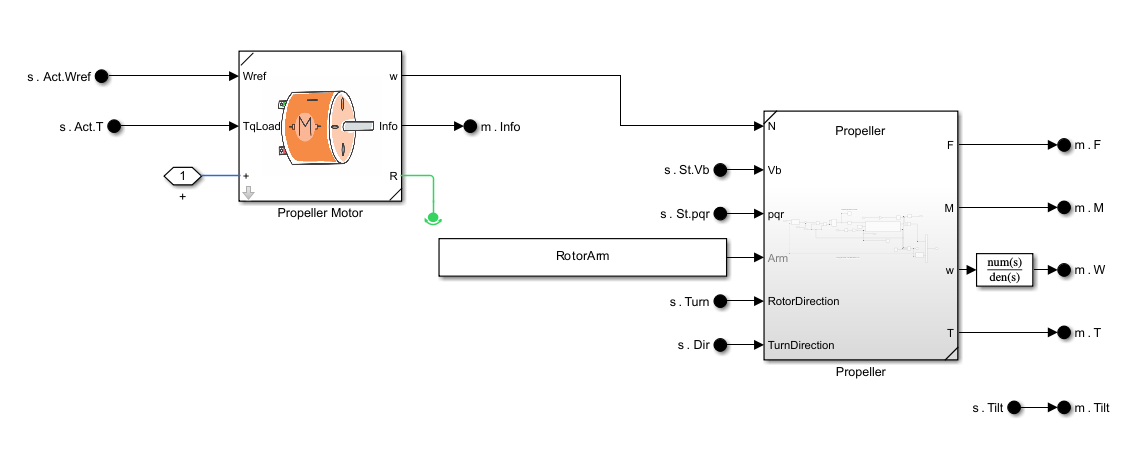

The propeller motor consists of a Motor and Drive block, which connects to the battery for power and drives the attached propeller. A speed controller manages the motor and propeller speed according to the values calculated by the airframe controller. All four motors are identical and each has a corresponding speed controller. Open the Propeller Motor subsystem.

open_system('EVTOLTiltrotor/Powertrain/Propulsion System 1/Propeller Motor')

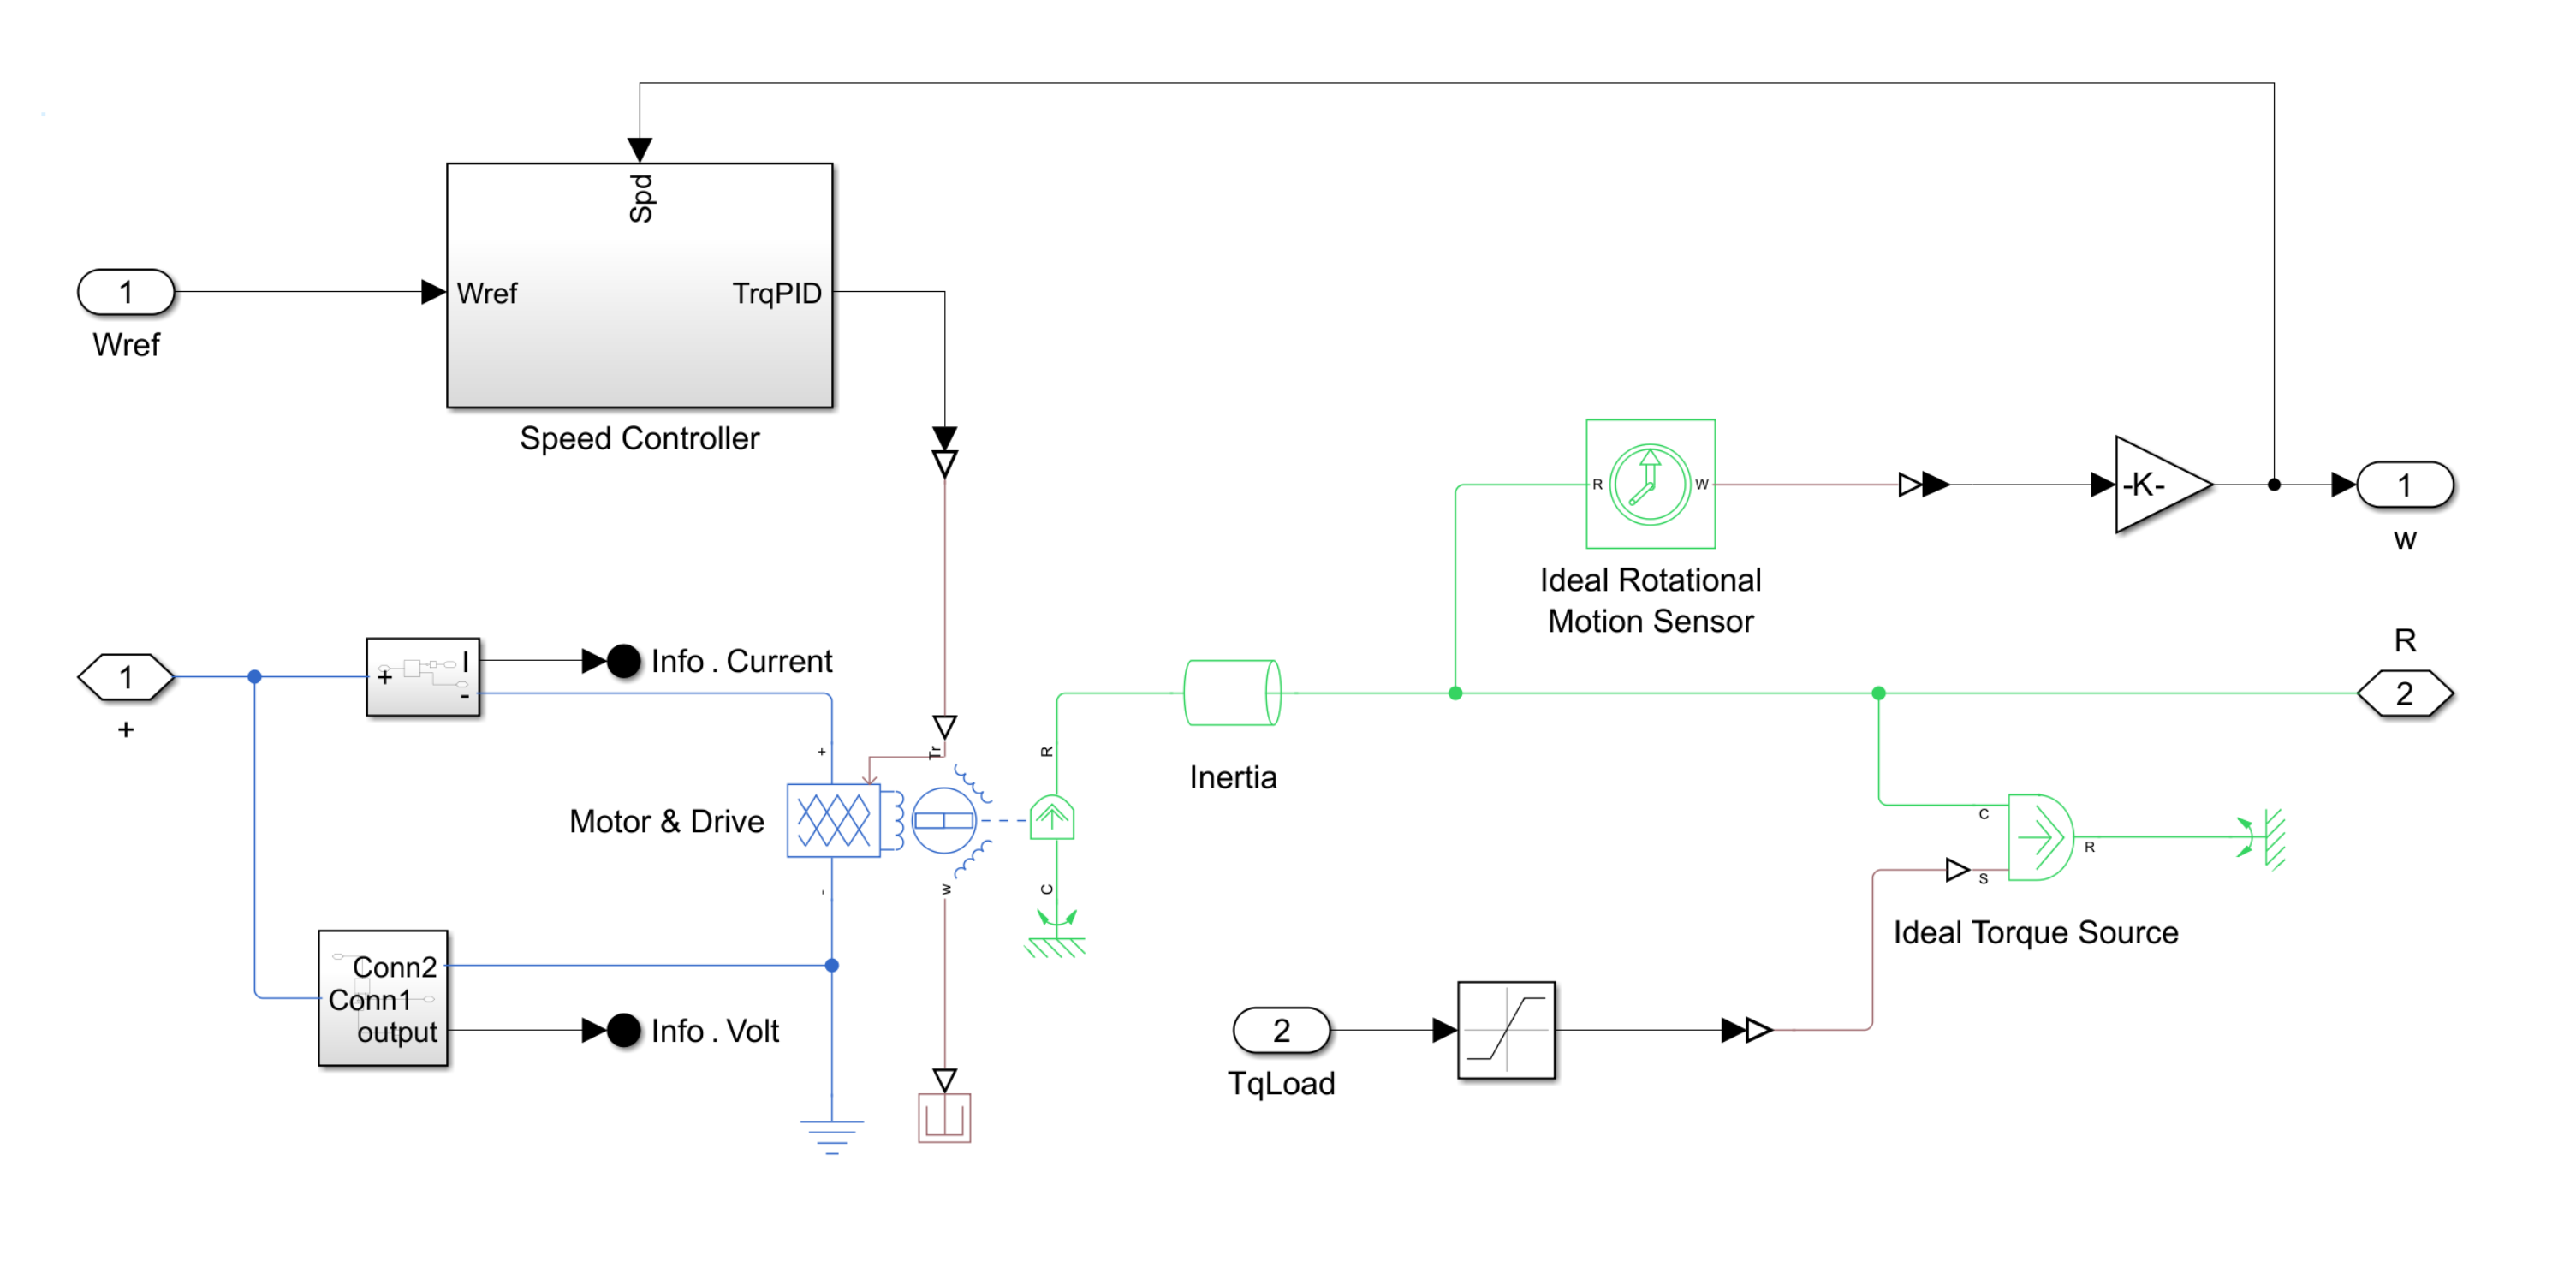

## Control Architecture

The flight control system consists of:

- **Outer loop** **—** To navigate and guide the aircraft.

- **Inner loops** **— **To control the attitude, roll, pitch, and yaw.

- **Motor loops** **— **To control the speed of the motor and propeller.

The outer loop manages high-level mission planning and path-following tasks, incorporating waypoint navigation, trajectory generation, and path-following algorithms. The inner loop controls the orientation of the UAV to maintain stability using separate PID controllers for the roll, pitch, and yaw. Control commands are converted to motor speed adjustments using a mixer, converting roll, pitch, yaw, and throttle inputs into individual motor speeds and regulating the speed of each motor based on the mixing output. For more information about the control architecture see [1].

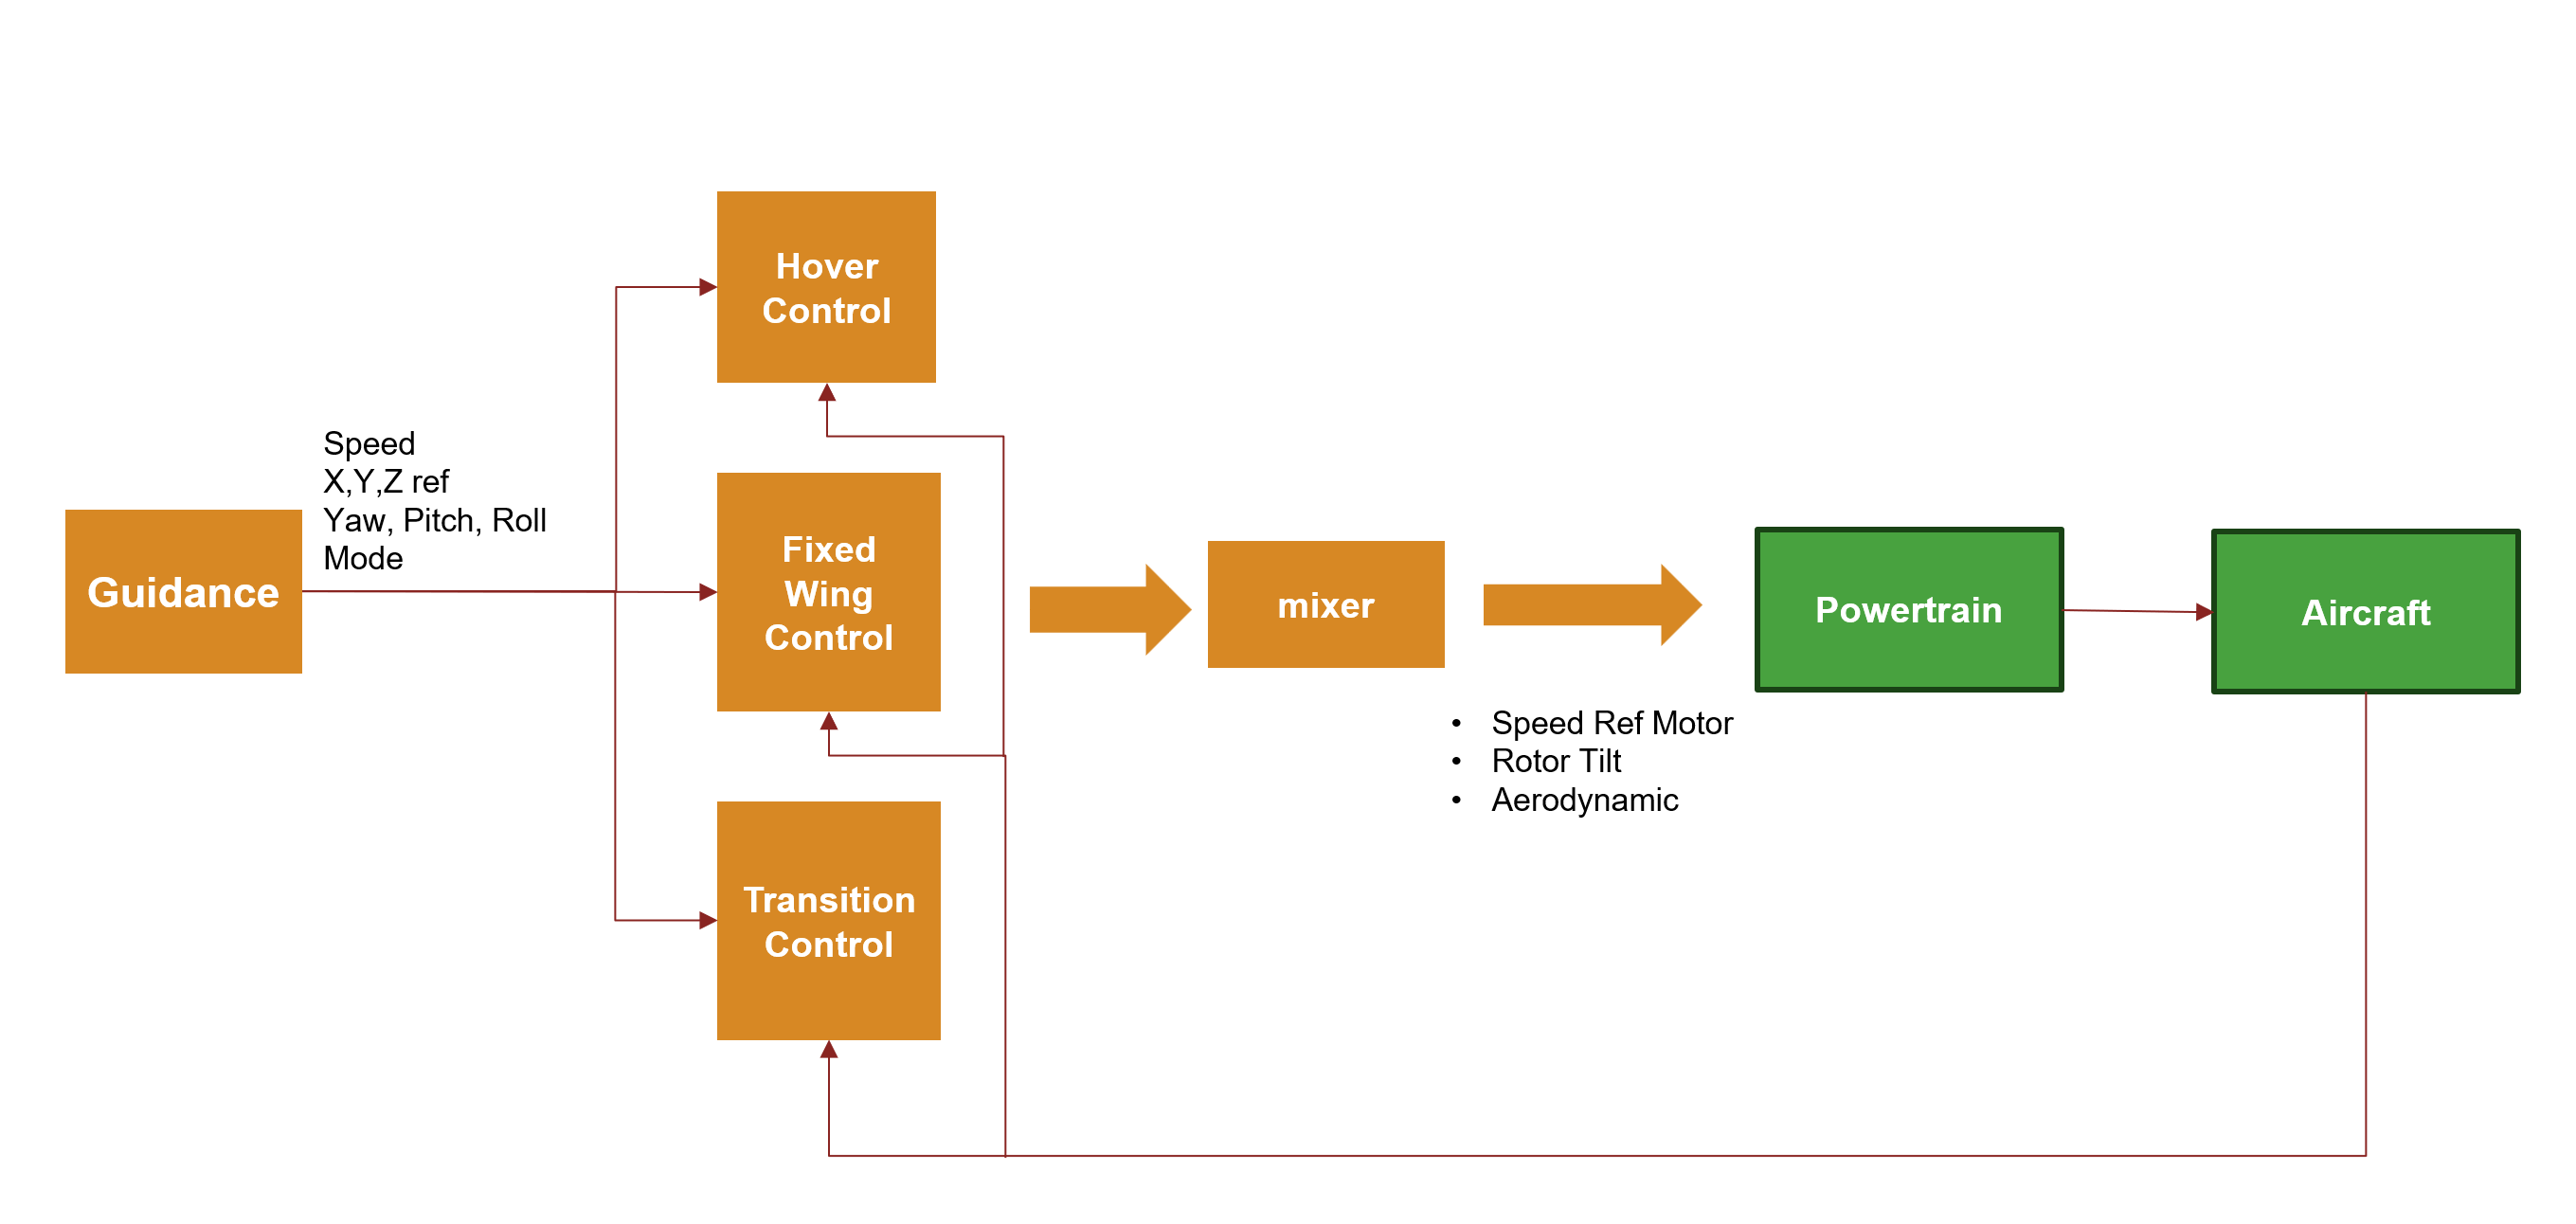

The Powertrain subsystem receives the outputs from the airframe controllers, including the setpoints for motor speeds, rotor tilt, and lateral aerodynamic controls. The motor reference speed setpoint serves as the input to the motor speed controller, a PID controller, which generates the necessary torque for the motor to maintain the desired speed. A Motor and Drive block models a simplified motor by receiving the torque command as input. The propeller attaches as a load to the motor shaft.

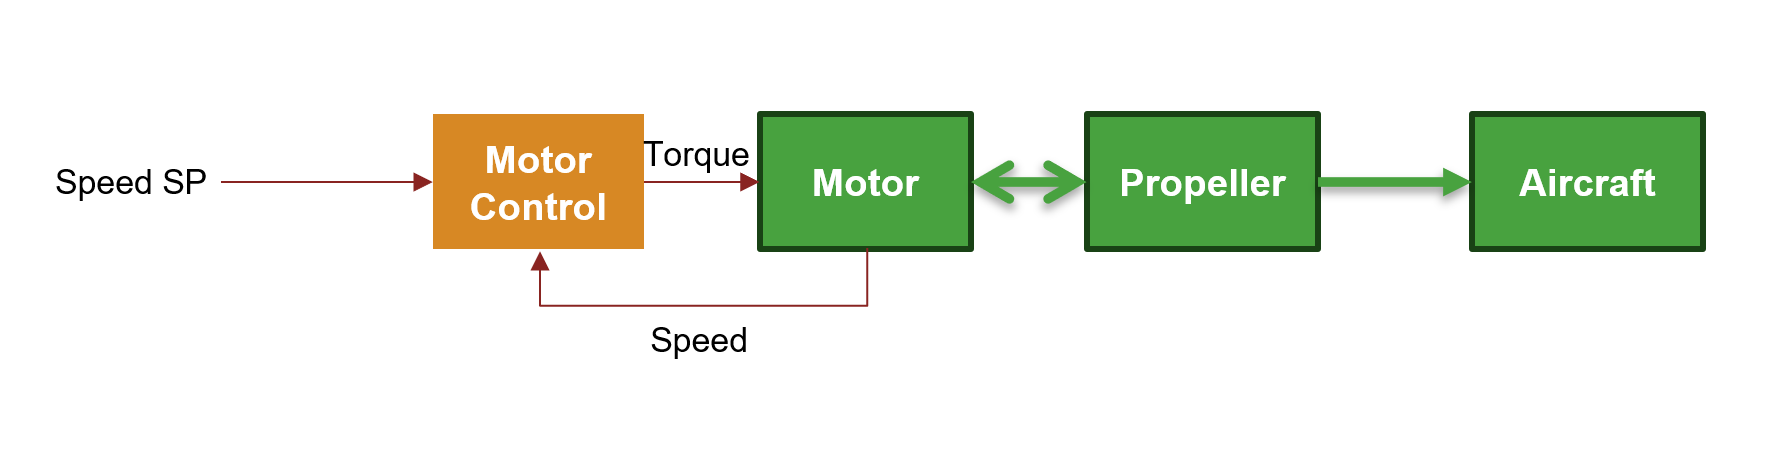

The motor loop is the innermost loop of the cascaded control architecture and requires careful tuning to ensure optimal performance.

## **References**

[1] N., Pavan. (2020). “Design of Tiltrotor VTOL and Development of Simulink Environment for Flight Simulations.” Master's Thesis, Indian Institute of Technology Madras, 2020 [here](https://www.researchgate.net/profile/Pavan-N/publication/351154528_Design_of_Tiltrotor_VTOL_and_Development_of_Simulink_Environment_for_Flight_Simulations/links/608ab0eba6fdccaebdf77bc8/Design-of-Tiltrotor-VTOL-and-Development-of-Simulink-Environment-for-Flight-Simulations.pdf).